**第11讲 插 值**

### **11.1****  插值概述**

        设函数$f\left(x\right)$`在`$\left\lbrack a,b\right\rbrack$`上有定义，且已知`$f\left(x\right)$`在`$\left\lbrack a,b\right\rbrack$`上`$n+1$`个互异节点`$x_0$,$x_1$,$\cdots ,x_n$的函数值$f\left(x_0 \right)$,$f\left(x_1 \right)$,$\cdots ,f\left(x_n \right)$,若存在一个不超过n次的多项式$P_n$$\left(X\right)$,满足

$P_n$$\left(x_i \right)$=$f$$\left(x_i \right)$     ($i=0,1,2\cdots ,n$)          $\left(11-1\right)$      

        则称$P_n$$\left(X\right)$为$f\left(x\right)$的n次插值多项式，式$\left(11-1\right)$为插值条件，$x_i$为插值节点，$f\left(x\right)$为被插函数，$R_n \left(x\right)=f\left(x\right)-P_n \left(x\right)$为插值多项式的余项。

### **11.2 Lagrange插值**

        Lagrange插值法是一种比较常用的插值方法，根据函数$f\left(x\right)$`在区间`$\left\lbrack a,b\right\rbrack$`上的已知数据点`$\left(x_k ,f\left(x_k \right)\right),\left(k=0,1,\cdots ,n\right)$,n阶Lagrange插值公式可以写为


$$f\left(x\right)=L_n \left(x\right)+R_n \left(x\right)=\sum_{k=0}^n f\left(x_k \right)l_k \left(x\right)+\frac{f^{\left(n+1\right)} \left(\xi \right)}{\left(n+1\right)!}W_{n+1} \left(x\right)\;\;\;\;\;\;\;\;\;\;\left(11-2\right)$$


        式中

$l_k \left(x\right)$=$\Pi_{i=0,i\not= k}^n \frac{x-x_i }{x_k -x_i }\left(k=0,1,2\cdots ,n\right)\;\;\;\;\;\;\;\;\;\;\left(11-3\right)$


$$W_{n+1} \left(x\right)=\Pi_{i=0}^n \left(x-x_i \right)\;\;\;\;\;\;\;\;\;\;\left(11-4\right)$$


        称


$$L_n \left(x\right)=\Sigma_{k=0}^n f\left(x_k \right)l_k \left(x\right)\;\;\;\;\;\;\;\;\;\;\left(11-5\right)$$


        为$f\left(x\right)$的$n$次$\textrm{Lagrange}$插值多项式，$R_n \left(x\right)$为插值多项式的余项，它表示用$L_n \left(x\right)$代替$f\left(x\right)$时在点$x$处产生的误差，式$\left(11-3\right)$称为$\textrm{Lagrange}$插值基函数。

**代码实现：**MATLAB中没有提供专门的函数计算Lagrange插值，需自行编写代码实现。

** 计算**$\textrm{Lagrange}$插值程序代码：

**function y=lagrange_interp(xdata,ydata,x)**

**% Lagrange插值**

**% 输入参数：**

**%       ---xdata：给定的节点横坐标**

**%       ---ydata：给定的节点纵坐标**

**%       ---x：需要进行插值的节点横坐标**

**% 输出参数：**

**%       ---y：Lagrange插值函数在x处的函数值**

**n=length(xdata);m=length(ydata);**

**if n~=m**

**    error('插值数据长度不等！');**

**end**

**ii=1:n;y=zeros(size(x));**

**for i=ii**

**    ij=find(ii~=i);V=1;**

**    for j=1:length(ij)**

**        if abs(xdata(i)-xdata(ij(j)))<eps**

**            error('输入的n+1个节点不是互异的。');**

**        end**

**        V=V.*(x-xdata(ij(j)));**

**    end**

**    y=y+V*ydata(i)/prod(xdata(i)-xdata(ij));**

**end**

**或**

function y=lagrange_interp_hwj(xdata,ydata,x)

% Lagrange插值

% 输入参数：

%       ---xdata：给定的节点横坐标

%       ---ydata：给定的节点纵坐标

%       ---x：需要进行插值的节点横坐标

% 输出参数：

%       ---y：Lagrange插值函数在x处的函数值

    n=length(xdata);m=length(ydata);

    if n~=m

        error('插值数据长度不等！');

    end

    % 数据互异性检查

    for i=1:n-1

        for j=(i+1):n

            if abs(xdata(i)-xdata(j))<eps

                error('输入的n+1个节点不是互异的。');

            end

        end

    end

    ii=1:n; y=zeros(size(x));

    V = ones(n,length(x));

    for i=ii

        ij=find(ii~=i);

        for j=1:length(ij)

            V(i,:)=V(i,:).*(x-xdata(ij(j)))/(xdata(i)-xdata(ij(j)));

        end

    end

    y = ydata*V;   % 需保证y是行向量

end

**%该函数的调用格式为：**

**y=lagrange_interp(xdata,ydata,x)**

**【例11-1】**导线中的电流与时间的函数关系测量下表所示，已知测量值的精度很高。

 表11-1 电流与时间的函数关系

试计算在时间$t=0\ldotp 01k\left(k=0,1,2,\cdots ,50\right)$时的电流值$i$。

由题中给定的条件“测量值的精度很高”可知，应利用插值法进行求解。

xdata=0:0.125:0.5;  % 时间向量
ydata=[0 6.24 7.75 4.85 0];  % 导体中的电流值
xi=0:0.01:0.5;  % 加密时间向量
tic
yi=lagrange_interp_hwj(xdata,ydata,xi);  % Lagrange插值
toc

历时 0.012048 秒。


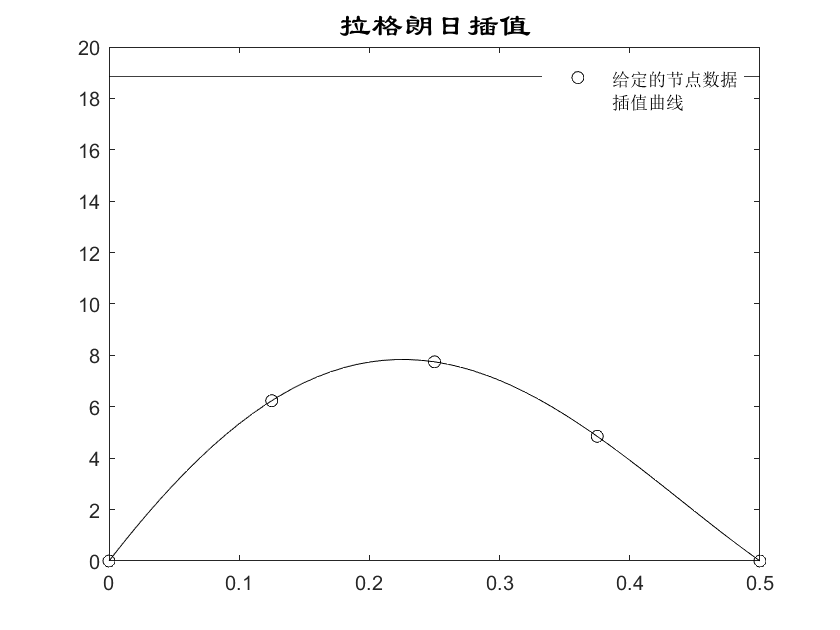

plot(xdata,ydata,'ko')  % 绘制时间-电流图形
hold on  % 图形保持
plot(xi,yi,'k')  % 绘制插值后的结果
title('\fontname{隶书}\fontsize{16}拉格朗日插值')  % 添加标题
legend('给定的节点数据','插值曲线')  % 添加图例

### **11.3 Newton插值**

        利用插值基函数能很容易地得到$\textrm{Lagrange}$插值多项式。而且公式结构紧凑，在理论分析中也很方便，但是$\textrm{Lagrange}$插值法也有其不可忽略的缺点：**当插值节点增加时，全部插值基函数均要随之变化，整个计算工作必须要重新开始，即没有“承袭性”**。为了克服这一缺点，可引入$\textrm{Newton}$插值法。

        为了更好地理解$\textrm{Newton}$插值原理，这里先介绍一下差商的概念：设已知函数$f\left(x\right)$在$\left\lbrack a,b\right\rbrack$上$n+1$个互异节点$x_0$,$x_1$,$\cdots ,x_n$的函数值$f\left(x_0 \right)$,$f\left(x_1 \right)$,$\cdots ,f\left(x_n \right)$，称


$$\frac{f\left(x_j \right)-f\left(x_i \right)}{x_j -x_i }$$


        为$f\left(x\right)$关于节点$x_i$,$x_j$的1阶差商，记为$f\left\lbrack x_i ,x_j \right\rbrack$,即


$$f\left\lbrack x_i ,x_j \right\rbrack =\frac{f\left(x_j \right)-f\left(x_i \right)}{x_j -x_i }\;\;\;\;\;\;\;\;\;\;\left(11-6\right)$$


        称1阶差商$f\left\lbrack x_i ,x_j \right\rbrack$和$f\left\lbrack x_j ,x_k \right\rbrack$的差商


$$\frac{f\left\lbrack x_j ,x_k \right\rbrack -f\left\lbrack x_i ,x_j \right\rbrack }{x_k -x_i }$$


        为$f\left(x\right)$关于节点$x_i ,x_j$和$x_k$的2阶差商，记为$f\left\lbrack x_i ,x_j ,x_k \right\rbrack$,即


$$f\left\lbrack x_i ,x_j ,x_k \right\rbrack =\frac{f\left\lbrack x_j ,x_k \right\rbrack -f\left\lbrack x_i ,x_j \right\rbrack }{x_k -x_i }\;\;\;\;\;\;\;\;\;\;\left(11-7\right)$$


        一般地，称$\left(k-1\right)$阶差商的差商为$k$阶差商，即


$$f\left\lbrack x_0 ,x_1 ,\cdots ,x_{k-1} ,x_k \right\rbrack =\frac{f\left\lbrack x_1 ,x_{2,} \cdots ,x_k \right\rbrack -f\left\lbrack x_0 ,x_1 ,\cdots ,x_{k-1} \right\rbrack }{x_k -x_0 }\;\;\;\;\;\;\;\;\;\;\left(11-8\right)$$


        这里约定$f\left\lbrack x_i \right\rbrack =f\left(x_i \right)$为$f\left(x\right)$关于节点$x_i$的零阶差商。

        由差商的定义可知：若给定$f\left(x\right)$在$n+1$个互异节点$x_0$,$x_1$,$\cdots ,x_n$上的函数值，则可求出直至$n$的各阶差商。

        根据差商的定义，$\textrm{Newton}$插值法的插值公式可以写为：


$$\begin{array}{l}
f\left(x\right)=N_n \left(x\right)+R_n \left(x\right)\\
\;\;\;\;\;\;\;\;\;\;=f\left\lbrack x_0 \right\rbrack +f\left\lbrack x_0 ,x_1 \right\rbrack \left(x-x_0 \right)+f\left\lbrack x_0 ,x_1 ,x_2 \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)+\cdots \\
\;\;\;\;\;\;\;\;\;\;+f\left\lbrack x_0 ,x_1 \cdots ,x_n \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)\cdots \left(x-x_{n-1} \right)\\
\;\;\;\;\;\;\;\;\;\;+f\left\lbrack x_0 ,x_1 ,x_2 \cdots ,x_n ,x\right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)\cdots \left(x-x_n \right)\;\;\;\;\;\;\;\;\;\;
\end{array}$$
          
$$\left(11-9\right)$$


        式中


$$\begin{array}{l}
N_n \left(x\right)=f\left(x_0 \right)+f\left\lbrack x_0 ,x_1 \right\rbrack \left(x-x_0 \right)+f\left\lbrack x_0 ,x_1 ,x_2 \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)+\\
\;\;\;\;\;\;\;\;\;\;\;\;\cdots +f\left\lbrack x_0 ,x_1 ,\cdots ,x_n \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)\cdots \left(x-x_{n-1} \right)\;\;\;\;\;\;\;\;\;\;\left(11-10\right)
\end{array}$$
          
$$\left(11-10\right)$$


        称为$f\left(x\right)$的$n$次$\textrm{Newton}$插值多项式，$R_n \left(x\right)$为$\textrm{Newton}$插值多项式的余项。

表11-2 差商表

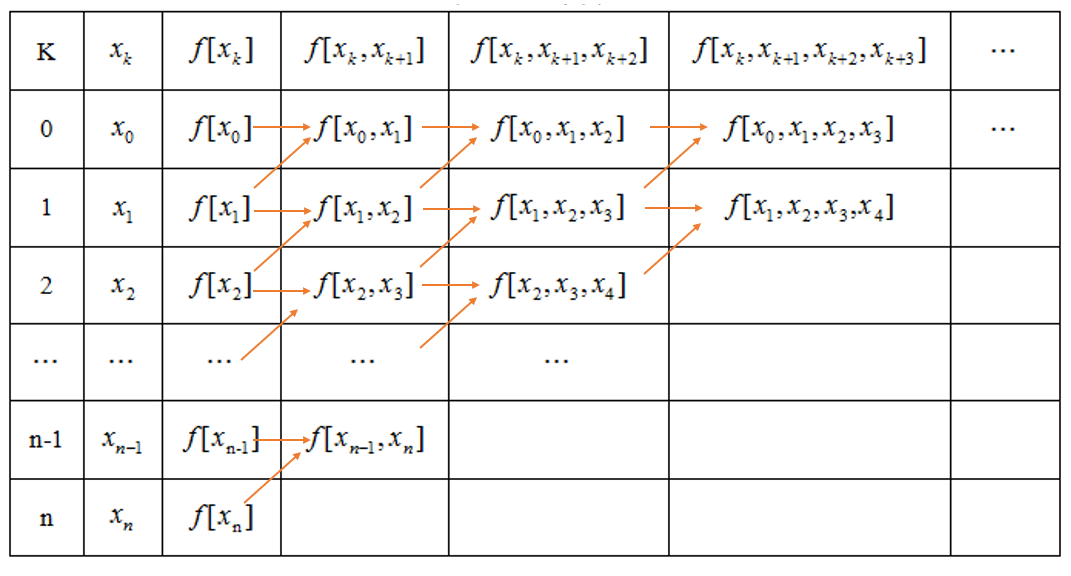

MATLAB没有提供现成的函数求解Newton插值，需自行编写代码实现：

针对式11-9中Newton插值的计算，要分别实现表11-2的差商表和 

**思考：这两部分的计算如何编写代码实现？**

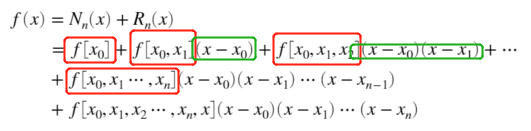

**-- 差商表的实现：**

for j=1:n-1

    for k=1:n-j

        D(k,j+1)=(D(k+1,j)-D(k,j))/(xdata(j+k)-xdata(k));

    end

end

**-- ** **的代码实现：**

H=1;

for j=1:n-1 

    H=H.*(x-xdata(j));

    L(j,:)=H;

%或  L(j,:) = prod((x-xdata(1:j).'))

end

或： 

---------------------------------------------

**总的牛顿插值算法实现函数：**

function [y,D]=newton_interp(xdata,ydata,x)

% Newton插值

% 输入参数：

%       ---xdata：给定的节点横坐标

%       ---ydata：给定的节点纵坐标

%       ---x：需要进行插值的节点横坐标

% 输出参数：

%       ---y：Newton插值函数在x处的函数值

%       ---D：差商表

n=length(xdata);m=length(ydata);

if n~=m

    error('插值数据长度不等！');

end

D=zeros(n);D(:,1)=ydata';H=1;

for j=1:n-1

    for k=1:n-j

        if abs(xdata(j+k)-xdata(k))<eps

            error('输入的n+1个节点不是互异的。');

        end

   **     D(k,j+1)=(D(k+1,j)-D(k,j))/(xdata(j+k)-xdata(k));**

    end

**    H=H.*(x-xdata(j));**

    L(j,:)=H;

end

L=[ones(size(x));L];    % 1, (x-x0), (x-x0)(x-x1),...

**y=L.*repmat(D(1,:)',1,length(x));**

y=sum(y);

%该函数的调用格式为：

[y,D]=newton_interp(xdata,ydata,x)

【例11-2】利用$\textrm{Newton}$插值求解【例11-1】：

xdata=0:0.125:0.5;  % 时间向量
ydata=[0 6.24 7.75 4.85 0];  % 导体中的电流值
xi=0:0.01:0.5;  % 加密时间向量
[yi,D]=newton_interp(xdata,ydata,xi);  % Newton插值
plot(xdata,ydata,'ko')  % 绘制已知数据点
hold on  % 图形保持
plot(xi,yi,'k')  % 绘制插值后的图形
disp('差商表D：')  % 显示差商表D
disp(D)
title('\fontname{隶书}\fontsize{16}牛顿插值')  % 添加标题
legend('给定的节点数据','插值曲线')  % 添加图例

### **11.4 Hermite插值**

 前面介绍的插值公式，都只要求插值多项式在插值多项式在插值节点处给定的函数值**。**

**在实际问题中，有时不仅要求插值多项式**$P_n \left(x\right)$**与函数**$f\left(x\right)$**在插值节点**$x_0$**,**$x_1$**,**$\cdots ,x_n$**上的函数值相等，而且还要求在这些点上的若干阶导数也相等，**这就需要引入$\textrm{Hermite}$插值。

       对于有高阶导数的情况，$\textrm{Hermite}$插值多项式比较复杂，在实际应用中，常常遇到的是函数值为一阶导数值给定的情况。在这种条件下，对于$n+1$个互异节点$x_0$,$x_1$,$\cdots ,x_n$，$\textrm{Hermite}$插值公式可以写为：


$$f\left(x\right)=H_{2n+1} \left(x\right)+R_{2n+1} \left(x\right)=\sum_{i=0}^n h_i \left(x\right)f\left(x_i \right)+\sum_{i=0}^n g_i \left(x\right)f^{\prime } \left(x_i \right)+\frac{f^{\left(2n+2\right)} \left(\xi \right)}{\left(2n+2\right)!}\Pi_{i=0}^n {\left(x-x_i \right)}^2 \;\;\;\;\;\;\;\;\;\;\left(11-11\right)$$


       式中


$$h_i \left(x\right)=\left\lbrack 1-2\left(x-x_i \right)\Sigma_{j=0,j\not= i}^n \frac{1}{x_i -x_j }\right\rbrack {l_i }^2 \left(x\right)\;\;\;\;\;\;\;\;\;\;\left(11-12\right)$$



$$g_i \left(x\right)=\left(x-x_i \right){l_i }^2 \left(x\right)\;\;\;\;\;\;\;\;\;\;\left(11-13\right)$$


       称


$$H_{2n+1} \left(x\right)=\Sigma_{i=0}^n h_i \left(x\right)f\left(x_i \right)+\Sigma_{i=0}^n g_i \left(x\right)f^{\prime } \left(x_i \right)\;\;\;\;\;\;\;\;\;\;\left(11-14\right)$$


       为$f\left(x\right)$的$2n+1$次$\textrm{Hermite}$插值多项式。

根据式$\left(6-14\right)$编写计算$\textrm{Hermite}$插值的程序：

function y=hermite_interp(xdata,ydata,ydot,x)

% hermite插值

% 输入参数：

%       ---xdata：给定的节点横坐标

%       ---ydata：给定的节点纵坐标

%       ---ydot：给定插值节点处的导数值，其缺省值用均差代替

%       ---x：需要进行插值的节点横坐标

% 输出参数：

%       ---y：Lagrange插值函数在x处的函数值

if isempty(ydot)==1

    ydot=gradient(ydata,xdata);

end

n=length(xdata);m=length(ydata);h=length(ydot);y=zeros(size(x));

if n~=m|n~=h|m~=h

    error('插值数据长度不等！')

end

ii=1:n;y=zeros(size(x));

for i=ii

    ij=find(ii~=i);V=1;

    for j=1:length(ij)

        if abs(xdata(i)-xdata(ij(j)))<eps

            error('输入的n+1个节点不是互异的。');

        end

        V=V.*(x-xdata(ij(j))).^2/(xdata(i)-xdata(ij(j)))^2;    % li(x)^2

    end

    %  $H_{2n+1} \left(x\right)=\Sigma_{i=0}^n h_i \left(x\right)f\left(x_i \right)+\Sigma_{i=0}^n g_i \left(x\right)f^{\prime } \left(x_i \right)\;\;\;\;\;\;\;\;\;\;$

% $h_i \left(x\right)=\left\lbrack 1-2\left(x-x_i \right)\Sigma_{j=0,j\not= i}^n \frac{1}{x_i -x_j }\right\rbrack {l_i }^2 \left(x\right)\;\;\;\;\;\;\;\;\;\;$

%  $g_i \left(x\right)=\left(x-x_i \right){l_i }^2 \left(x\right)\;\;\;\;\;\;\;\;\;\;$

    y=y+V.*((1-2*(x-xdata(i))*sum(1./(xdata(i)-xdata(ij))))*...

        ydata(i)+(x-xdata(i))*ydot(i));

end

%该函数的调用格式为：

y=hermite_interp(xdata,ydata,ydot,x)

【例11-3】利用$\textrm{Hermite}$插值重新求解例11-1，节点处的导数值利用$\textrm{rand}\left(1,5\right)-0\ldotp 5$得到。

xdata=0:0.125:0.5;  % 时间向量
ydata=[0 6.24 7.75 4.85 0];  % 电流值
xi=0:0.01:0.5;  % 加密时间向量
rand('state',0)  % 设定随机数状态
doty = rand(1,5)-0.5;
yi=hermite_interp(xdata,ydata,doty,xi);  % Hermite插值
plot(xdata,ydata,'ko')  % 绘制已知数据点
hold on  % 图形保持
plot(xi,yi,'k')  % 绘制插值后的图形
title('\fontname{隶书}\fontsize{16}埃尔米特插值')  % 添加标题
legend('给定的节点数据','插值曲线')  % 添加图例


### **11.5 分段低次插值**

       为了说明分段插值的必要性，考虑一个典型的例子：设$f\left(x\right)=\frac{1}{1+25x^2 },x\in \left\lbrack -1,1\right\rbrack$假设已知其中一些点的坐标，则可以采用下面的命令进行$\textrm{Lagrange}$插值，得出如图所示的插值曲线。

x=-1:0.01:1;  % 加密数据点
xdata=-1:0.2:1;  % 已知数据点
ydata=1./(1+25*xdata.^2);  % 点xdata处的函数值
y=lagrange_interp(xdata,ydata,x);  % Lagrange插值
plot(xdata,ydata,'ko',x,y,'k',x,1./(1+25*x.^2))%绘制图形

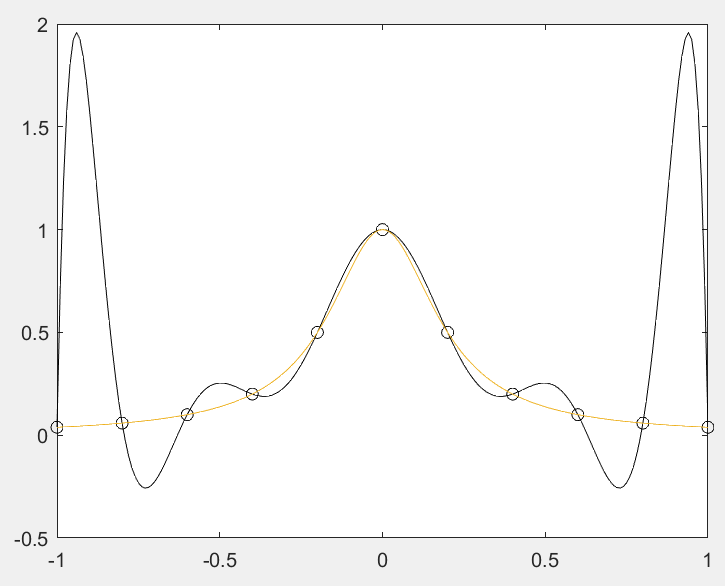

可见，用Lagrange插值得出的效果和精确值相差甚远，出现多项式阶次越高越发散的现象。

鉴于高阶多项式插值的弊端，引入分段低次插值，分段低次插值主要有分段线性插值和分段Hermite插值两种。

#### 11.5.1 分段线性插值

       所谓分段线性插值就是通过将相邻的两个插值点用线段连接，如此形成的一条折线来逼近函数$f\left(x\right)$。给定$f\left(x\right)$在$n+1$个节点$a=x_0 <x_1 <\cdots <x_n =b$上的函数值$f\left(x_0 \right)$,$f\left(x_1 \right)$,$\cdots ,f\left(x_n \right)$，在每个小区间$\left\lbrack x_i ,x_{i+1} \right\rbrack$上线性插值


$$L_{1,i} \left(x\right)=f\left(x_i \right)+f\left\lbrack x_i ,x_{i+1} \right\rbrack \left(x-x_i \right),x\in \left\lbrack x_i ,x_{i+1} \right\rbrack \;\;\;\;\;\;\;\;\;\;\left(11-15\right)$$


将差商式子代入，得到     $L_{1,i} \left(x\right)=f\left(x_i \right)\frac{x-x_{i+1} }{x_i -x_{i+1} }+f\left(x_{i+1} \right)\frac{x-x_i }{x_{i+1} -x_i }$

若用插值基函数表示，则在整个区间$\left\lbrack a,b\right\rbrack$上$f\left(x\right)$的分段线性插值函数可以表示为


$$\tilde{L_1 } \left(x\right)=\Sigma_{i=0}^n f\left(x_i \right)l_i \left(x\right)\;\;\;\;\;\;\;\;\;\;\left(11-16\right)$$


其中


$$l_i \left(x\right)={\left\{\begin{array}{c}
\frac{x-x_{i-1} }{x_i -x_{i-1} },x\in \left\lbrack x_{i-1} ,x_i \right\rbrack ,0<i\le n\\
\frac{x-x_{i+1} }{x_i -x_{i+1} },x\in \left\lbrack x_i ,x_{i+1} \right\rbrack ,0\le i<n\\
\\
0,\textrm{其他}
\end{array}\right)}\;\;\;\;\;\;\;\;\;\;\left(11-17\right)$$


$\tilde{L_1 } \left(x\right)$有良好的收敛性，即对于$x\in \left\lbrack a,b\right\rbrack$时，有$\lim_{n\to \infty } \tilde{L_1 } \left(x\right)=f\left(x\right)$。

感兴趣的同学可以利用式（11-16）和式（11-17）动手编写分段线性插值的代码实现，MATLAB提供了函数interp1()可以实现分段线性插值功能，调用方法如下：

y=interp1(x,y,xi,'linear')

其中，x为插值节点构成的向量，y是插值节点函数值构成的向量，$y_i$是被插值点$x_i$的插值结果，选项**'linear'**表示线性插值（默认值）

【例11-4】利用$\textrm{interp1}$()函数对$f\left(x\right)=\frac{1}{1+25x^2 },x\in \left\lbrack -1,1\right\rbrack$进行分段线性插值。

x=-1:0.01:1;  % 加密数据点
xdata=-1:0.2:1;  % 已知数据点
ydata=1./(1+25*xdata.^2);  % 点xdata处的函数值
yi=interp1(xdata,ydata,x);  % 线性插值
subplot(2,1,1)  % 图形分割
plot(x,1./(1+25*x.^2),'k',x,yi,'k:',xdata,ydata,'ko')  % 绘制图形
legend('解析曲线','分段线性插值曲线')  % 添加图例
text(-0.9,0.9,'\fontname{隶书}\fontsize{16}分段线性插值')  % 添加标注
subplot(2,1,2)  % 图形分割
plot(x,yi-1./(1+25*x.^2),'k')  % 绘制图形
legend('分段线性插值误差曲线')  % 添加图例

#### 11.5.2 分段$\textrm{Hermite}$插值

       给定$f\left(x\right)$在$n+1$个节点$a=x_0 <x_1 <\cdots <x_n =b$上的函数值$f\left(x_0 \right)$,$f\left(x_1 \right)$,$\cdots ,f\left(x_n \right)$和一阶导数值$f^{\prime } \left(x_0 \right)$,$f^{\prime } \left(x_1 \right)$,$\cdots ,f^{\prime } \left(x_n \right)$，则可在每个小区间$\left\lbrack x_i ,x_{i+1} \right\rbrack$上构造三次$\textrm{Hermite}$插值多项式近似被插函数。

$\begin{array}{l}
H_{3,i} ={\left(\frac{x-x_{i+1} }{x_i -x_{i+1} }\right)}^2 \left(1+2\frac{x-x_i }{x_{i+1} -x_i }\right)f\left(x_i \right)+{\left(\frac{x-x_i }{x_{i+1} -x_i }\right)}^2 \left(1+2\frac{x-x_{i+1} }{x_i -x_{i+1} }\right)f\left(x_{i+1} \right)\\
\;\;\;\;\;\;\;\;\;\;+{\left(\frac{x-x_{i+1} }{x_i -x_{i+1} }\right)}^2 \left(x-x_i \right)f^{\prime } \left(x_i \right)+{\left(\frac{x-x_i }{x_{i+1} -x_i }\right)}^2 \left(x-x_{i+1} \right)f^{\prime } \left(x_{i+1} \right)
\end{array}$          (11-18)

       若在整个区间$\left\lbrack a,b\right\rbrack$上定义一组分段三次插值基函数$\alpha_i \left(x\right)$和$\beta_i \left(x\right)\left(j=0,1,\cdots ,n\right)$,则在整个区间$\left\lbrack a,b\right\rbrack$上$f\left(x\right)$的分段三次$\textrm{Hermite}$插值函数为：

$\overset{~}{H_3 } \left(x\right)=\sum_{i=0}^n \left\lbrack f\left(x_i \right)\alpha_i \left(x\right)+f^{\prime } \left(x_i \right)\beta_i \left(x\right)\right\rbrack$          (11-19)

其中$\alpha_i \left(x\right)$和$\beta_i \left(x\right)$分别为：

$\alpha_i \left(x\right)={\left\{\begin{array}{c}
{\left(\frac{x-x_{i-1} }{x_i -x_{i-1} }\right)}^2 \left(1+2\frac{x-x_i }{x_{i-1} -x_i }\right),x\in \left\lbrack x_{i-1} ,x_i \right\rbrack ,0<i\le n\\
{\left(\frac{x-x_{i+1} }{x_i -x_{i+1} }\right)}^2 \left(1+2\frac{x-x_i }{x_{i+1} -x_i }\right),x\in \left\lbrack x_i ,x_{i+1} \right\rbrack ,0\le i<n\\
\\
0,\textrm{其他}
\end{array}\right)}$          (11-20)

$\beta_i \left(x\right)={\left\{\begin{array}{c}
{\left(\frac{x-x_{i-1} }{x_i -x_{i-1} }\right)}^2 \left(x-x_i \right),x\in \left\lbrack x_{i-1} ,x_i \right\rbrack ,0<i\le n\\
{\left(\frac{x-x_{i+1} }{x_i -x_{i+1} }\right)}^2 \left(x-x_i \right),x\in \left\lbrack x_i ,x_{i+1} \right\rbrack ,0\le i<n\\
\\
0,\textrm{其他}
\end{array}\right)}$          (11-21)

同样地，$\overset{~}{H_3 } \left(x\right)$也具有良好的收敛性，即对于$x\in \left\lbrack a,b\right\rbrack$时，$\lim_{n\to \infty } {\tilde{H} }_3 \left(x\right)=f\left(x\right)$。

       同分段线性插值一样，MATLAB提供了函数**pchip()**来求解分段三次Hermite插值，该函数的调用格式有以下两种：

yi=pchip(x,y,xi)%格式一
pp=pchip(x,y)%格式二

其中，输入参数的含义同interp1()函数，格式2中的返回值pp是一个结构体数组，需要调用ppval()函数来计算各因变量的数值。

       说明：(1)语句“yi=ppval(pp,xi)"可以实现与格式一相同的功能；

                  (2)函数pchip()的效果等同于**yi=interp1(x,y,xi,'pchip')**或**yi=interp1(x,y,xi,'cubic')**。

【例11-5】利用$\textrm{pchip}$()函数对$f\left(x\right)=\frac{1}{1+25x^2 },x\in \left\lbrack -1,1\right\rbrack$进行分段三次$\textrm{Hermite}$插值。

x=-1:0.01:1;
xdata=-1:0.2:1;
ydata=1./(1+25*xdata.^2);
% yi=pchip(xdata,ydata,x);  % 分段三次Hermite插值
% yi=interp1(xdata,ydata,x,'pchip');  % 调用函数interp1()的'pchip'选项进行分段三次Hermite插值

% yi=interp1(xdata,ydata,x,'cubic');  % 立方插值

% pp=pchip(xdata,ydata);  % 分段三次Hermite插值
% yi=ppval(pp,x);  % 求x处的分段三次Hermite插值多项式的函数值
subplot(2,1,1)  % 图形分割
plot(x,1./(1+25*x.^2),'k',x,yi,'k:',xdata,ydata,'ko')  % 绘制图形
legend('解析曲线','分段三次hermite插值')  % 添加图例
text(-0.9,0.8,{'分段三次','Hermite插值'},...
    'fontname','隶书','fontsize',16)  % 添加标注
subplot(2,1,2)  % 图形分割
plot(x,yi-1./(1+25*x.^2),'k')  % 绘制图形
legend(char('\fontsize{8}分段三次Hermite','插值误差曲线'),'Location','northwest');  % 添加图例
% legend('boxoff')  % 设置图例边框为无


### 11.6 三次样条插值

采用分段插值虽然计算简单，也具有一致收敛性，但光滑性比较差，有些实际问题对插值函数的光滑性有较高要求，需要用到样条函数插值。**样条曲线实际上是由分段三次曲线连接而成，在连接点处有二阶连续导数**。

     常用的三次样条函数：

       设在区间[a,b]上给的n+1个插值节点$a=x_0 <x_1 <\cdots <x_n =b$及其函数$f\left(x\right)$相应的值$f\left(x_i \right)\left(i=0,1,\cdots ,n\right)$如果函数$S\left(x\right)$在区间[a,b]上满足条件：

      ** (1)**$S\left(x\right)$**在每个小区间**$\left\lbrack x_i ,x_{i+1} \right\rbrack$**上是三次多项式；**

**       (2)**$S\left(x\right)$**在区间**$\left\lbrack a,b\right\rbrack$**上存在连续的二阶导数。**

**       则称**$S\left(x\right)$**是区间**$\left\lbrack a,b\right\rbrack$**上的三次样条函数。**

**若**$S\left(x\right)$**还满足**$S\left(x_i \right)=f\left(x_i \right)\left(i=0,1,\cdots ,n\right)$**,则称**$S\left(x\right)$**是区间**$\left\lbrack a,b\right\rbrack$**上的三次样条插值函数。**

             注意到$S\left(x\right)$在每个小区间$\left\lbrack x_i ,x_{i+1} \right\rbrack$上是三次多项式，因此$S^{\prime \prime } \left(x\right)$在此小区间上是一次式，若设$S^{\prime \prime } \left(x_i \right)=M_i$,$S^{\prime \prime } \left(x_{i+1} \right)=M_{i+1}$,则$S^{\prime \prime } \left(x\right)$的表达式可以写为


$$S^{\prime \prime } \left(x\right)=M_i +\frac{1}{h_i }\left(M_{i+1} -M_i \right)\left(x-x_i \right),x\in \left\lbrack x_i ,x_{i+1} \right\rbrack \;\;\;\;\;\;\;\;\;\;\left(11-22\right)$$


       其中$h_i =x_{i+1} -x_i \;,i=0,1,2,\cdots ,n-1$利用$S\left(x_{i+1} \right)=f\left(x_{i+1} \right)$即可求得上述方程的解为：


$$\begin{array}{l}
{S\left(x\right)=M}_i \frac{{\left(x_{i+1} -x\right)}^3 }{6h_i }+M_{i+1} \frac{{\left(x-x_i \right)}^3 }{6h_i }+\left(f\left(x_i \right)-\frac{M_i {h_i }^2 }{6}\right)\frac{x_{i+1} -x}{h_i }\\
\;\;\;\;\;\;\;\;\;+\left(f\left(x_{i+1} \right)-\frac{M_{i+1} {h_i }^2 }{6}\right)\frac{x-x_i }{h_i }\left(x\in \left\lbrack x_i ,x_{i+1} \right\rbrack ;i=0,1,\cdots ,n-1\right)
\end{array}$$
          
$$\left(11-23\right)$$


根据式（11-23）可以编写代码实现分段三次样条插值函数代码的编写。

       MATLAB提供函数spline()求解三次样条插值问题，该函数的一般调用格式有两种：

yi=spline(x,y,xi)%格式一
pp=spline(x,y)%格式二

其中各参数的含义同函数pchip()

       说明：(1)语句“yi=ppval(pp,xi)"可以实现与格式一相同的功能；

                  (2)函数spline()的效果等同于**yi=interp1(x,y,xi,'spline')**。

【例11-6】利用三次样条插值函数对$f\left(x\right)=\frac{1}{1+25x^2 },x\epsilon \left\lbrack -1,1\right\rbrack$进行三次样条插值。

x=-1:0.01:1;
xdata=-1:0.2:1;
ydata=1./(1+25*xdata.^2);
yi=spline(xdata,ydata,x);  % 三次样条插值
% yi=interp1(xdata,ydata,x,'spline');  % interp1()函数'spline'选项实现三次样条插值
% pp=spline(xdata,ydata);  % 三次样条插值
% yi=ppval(pp,x);
subplot(2,1,1)  % 图形分割
plot(x,1./(1+25*x.^2),'k',x,yi,'k:',xdata,ydata,'ko')  % 绘制图形
legend('解析曲线','三次样条插值')  % 添加图例
text(-0.9,0.8,'三次样条插值','fontname','隶书','fontsize',16)  % 添加标注
subplot(2,1,2)  % 图形分割
plot(x,yi-1./(1+25*x.^2),'k')  % 绘制图形
legend('三次样条插值误差曲线')  % 添加图例

interp1()函数还提供了几种不同插值类型问题的求解，如最邻近插值、三次插值等，其完整的调用格式如下：

yi=interp1(x,y,xi,method,'extrap')

其中，method表示指定的插值方法，包括以下几种：

**'nearest'---最邻近插值。**

**’linear‘---线性插值（默认值）。**

**’spline‘---三次样条插值。**

**’pchip‘---分段三次Hermite插值。**

**extrap表示对超出x范围的xi分量执行特殊的外插值法**；

【例11-7】有人对汽车进行了一个实验，即在行驶过程中先加速，然后保持匀速行驶一段时间，接着再加速，然后再保持匀速，如此交替。注意，整个实验过程中从未减速，在一组时间点上测得汽车的速度如表11-3所示。

【表11-3实验数据】

试用MATLAB中的interp1()函数对这些数据进行插值。

t=[0 20 40 56 68 80 84 96 104 110];  % 时间向量
v=[0 20 20 38 80 80 100 100 125 125];  % 速度值
ti = linspace(0,110);  % 加密时间向量
method={'nearest','linear','spline','pchip','cubic','v5cubic'};  % 插值方法
for k=1:6
    subplot(3,2,k)  % 图形分割
    vi=interp1(t,v,ti,char(method(k)));  % 插值
    plot(t,v,'ko',ti,vi,'k')  % 绘制图形
    axis tight  % 控制坐标轴
    title(['\fontname{times new roman}\fontsize{12}\it',char(method(k))])  % 添加标题
end

### 11.7 二维插值

       前面介绍的插值是一维插值问题，而实际中可能遇到自变量的个数为两个的插值问题，即二维插值问题。二维插值问题的数学描述是：构造一个二元函数$z=f\left(x,y\right)$，使其在矩形区域$\left\lbrack a,b\right\rbrack \times \left\lbrack c,d\right\rbrack$内系列点$\left(x_i ,x_j \right)$的函数值为$z_{i,j} =f\left(x_i ,y_j \right)$，利用函数$z=f\left(x,y\right)$计算该矩形区域内任意一点的函数值。

       根据数据点$\left(x_i ,x_j \right)$分布情况，二维插值问题可以分为两种情况：**网络节点插值和散乱节点插值**，其中**网格节点插值适用于节点比较规则的情况，即在包含所给节点的矩形区域内，节点由两组平行于坐标轴的直线的交点组成；散乱节点插值适用于一般的节点，多用于节点不太规则的情况**。

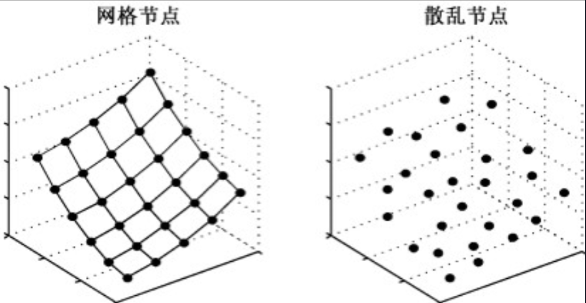

图 两种常见的介电分布

#### 11.7.1 网格节点插值

       已知$m\times n$个节点$\left(x_i ,y_i ,z_{i,j} \right)\left(i=0,1,2\cdots ,m;j=0,1,2,\cdots ,n\right)$，其中$x_i ,y_i$互不相同，不妨设$a=x_0 <x_1 <\cdots x_m =b,c=y_0 <y_1 <\cdots <y_n =d$，构造一个二元函数$z=f\left(x,y\right)$使其通过节点$\left(x_i ,y_i ,z_{i,j} \right)$，再利用函数$z=f\left(x,y\right)$求插值点$\left(x^* ,y^* \right)\left(\not= \left(x_i ,y_i \right)\right)$处的值$z^*$，这就是网络节点插值的数学描述。网格节点插值一般有以下几种形式。

**       1) 最近邻插值**

       最近邻插值是一种简单的插值算法，也称为零阶插值。在这种插值中，每一个插值点的函数值就是与其最邻近的网格点的函数值。

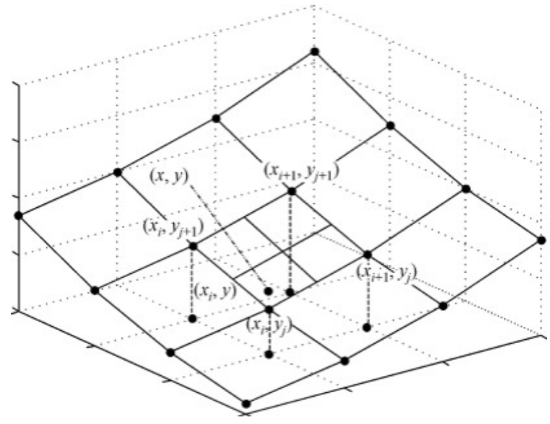

图 邻近插值图形表示

最邻近插值的数学表示为：

$f\left(x,y\right)=f\left(x_i ,y_i \right)$，当$\frac{x_i +x_{i-1} }{2}<x<\frac{x_i +x_{i+1} }{2}$且$\frac{y_j +y_{j-1} }{2}<y<\frac{y_j +y_{j+1} }{2}\;\;\;\;\;\;\;\;\;\;\left(11-24\right)$

       由式$\left(11-24\right)$可知，最邻近插值计算简单，但是通常是不连续的，因此一般用在对图像质量要求不高的场合。

**2) 分片线性插值**

       分片线性插值对应于一维插值中的分段线性插值，其基本思想是把所求区域分割成多个子矩形，即在以$\left(x_i ,y_j \right),\left(x_{i+1} ,y_j \right),\left(x_{i+1} ,y_{j+1} \right),\left(x_i ,y_{j+1} \right)$为顶点的小矩形$r_{\textrm{ij}}$上进行线性插值，如图所示。相应的分片插值函数如下所述。

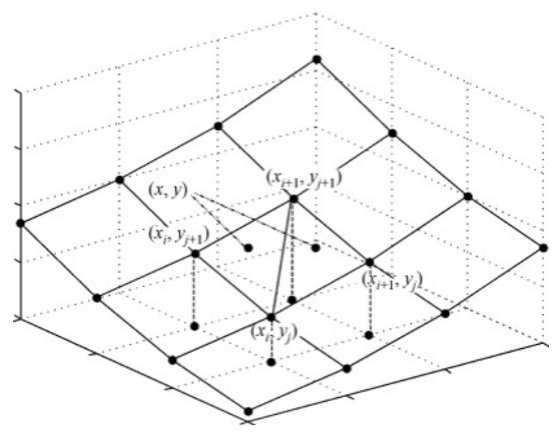

图 分片线性插值图形表示

第一片(下三角形区域):(x,y)满足$y\le \frac{y_{j+1} -y_j }{x_{i+1} -x_i }\left(x-x_i \right)+y_j$，插值函数为


$$f\left(x,y\right)=z_{i,j} +\frac{\left(z_{i+1,j} -z_{i,j} \right)}{x_{i+1} -x_i }\left(x-x_i \right)+\frac{\left(z_{i+1,j+1} -z_{i+1,j} \right)}{y_{j+1} -y_j }\left(y-y_i \right)\;\;\;\;\;\;\;\;\;\;\left(11-25\right)$$


第二片(上三角形区域):(x,y)满足$y>\frac{y_{j+1} -y_j }{x_{i+1} -x_i }\left(x-x_i \right)+y_j$，插值函数为


$$f\left(x,y\right)=z_{i,j} +\frac{\left(z_{i+1,j+1} -z_{i,j+1} \right)}{x_{i+1} -x_i }\left(x-x_i \right)+\left(\frac{z_{i,j+1} -z_{i,j} }{y_{j+1} -y_j }\right)\left(y-y_i \right)\;\;\;\;\;\;\;\;\;\;\left(11-26\right)$$


说明：分片线性插值对不同的片用不同的线性函数插值，因此，分片线性插值是连续的，但是光滑性不好。

**3) 双线性插值**

       双线性插值是最常见的线性插值算法，它是根据插值点周围最接近的4个点的函数值进行二维线性插值计算，如图所示，其具体计算过程如下所述。

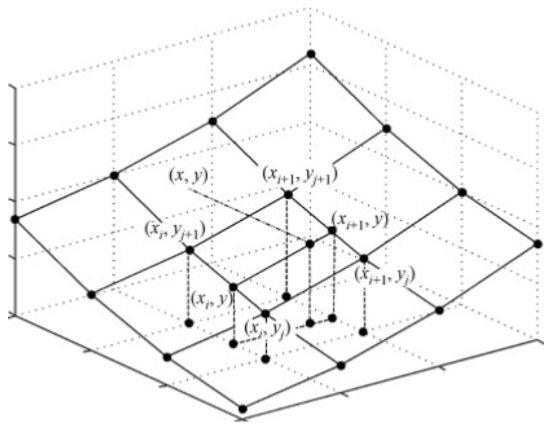

图 双线性插值图形表示

(1) 利用线性插值分别计算$f\left(x_i ,y\right)$和$f\left(x_{i+1} ,y\right)$


$$f\left(x_i ,y\right)=z_{i,j} +\frac{y-y_j }{y_{j+1} -y_j }\left(z_{i,j+1} -z_{i,j} \right)\;\;\;\;\;\;\;\;\;\;\left(11-27\right)$$



$$f\left(x_{i+1} ,y\right)=z_{i+1,j} +\frac{y-y_j }{y_{j+1} -y_j }\left(z_{i+1,j+1} -z_{i+1,j} \right)\;\;\;\;\;\;\;\;\;\;\left(11-28\right)$$


(2) 利用线性插值计算$f\left(x,y\right)$


$$f\left(x,y\right)=f\left(x_i ,y\right)+\frac{x-x_i }{x_{i+1} -x_i }\left\lbrack f\left(x_{i+1} ,y\right)-f\left(x_i ,y\right)\right\rbrack \;\;\;\;\;\;\;\;\;\;\left(11-29\right)$$


(3)将式$\left(11-27\right)$和式$\left(11-28\right)$代入式$\left(11-29\right)$中即可将$f\left(x,y\right)$化为如下形式：


$$f\left(x,y\right)=\left(\textrm{Ax}+B\right)\left(\textrm{Cy}+D\right),\left(x,y\right)\in r_{i,j} \;\;\;\;\;\;\;\;\;\;\left(11-30\right)$$


       其中A,B,C,D可以唯一确定，但是在相邻小矩形的4条边（不含定点）上不能保证连续。

**4) 双三次样条插值**

       双线性插值在子矩形$r_{\textrm{ij}}$上的数学表达式为$f\left(x,y\right)=\left(\textrm{Ax}+B\right)\left(\textrm{Cy}+D\right)$，将其稍加拓展，可以得到双三次样条插值在各个子矩形$r_{\textrm{ij}}$上的表达式为：


$$f\left(x,y\right)=\left(A_1 +A_2 x+A_3 x^2 +A_4 x^3 \right)\left(B_1 +B_2 y+B_3 y^2 +B_4 y^3 \right)\;\;\;\;\;\;\;\;\;\;\left(11-31\right)$$


       其中，待定系数$A_{i,} B_i \left(i=1,2,3,4\right)$可以由子矩形4个顶点的函数值及插值函数$f\left(x,y\right)$在x和y方向上的光滑性（即偏导数${f^{\prime } }_x \;,$${f^{\prime } }_y \;,{f^{\prime \prime } }_{\textrm{xx}}$和${f^{\prime \prime } }_{\textrm{yy}} \;$连续）和相应的边界条件唯一确定。

对于网格节点的插值，MATLAB提供了函数**interp2()**求解，其具体调用格式如下：

zi=interp2(x,y,z,xi,yi,method)%格式一
zi=interp2(x,y,z,xi,yi,method,extrapval)%格式二

       其中，x和y是长度分别为M和N的向量，对应着已知点$\left(x_i ,y_j \right)$，z是一个矩阵，对应于$Z_{i,j} \left(i=0,1,2,\cdots ,m;j=0,1,2\cdots ,n\right)$，其他参数的含义基本同interp1()函数。

【例】利用不同的插值方法对MATLAB自带的演示函数peaks进行二维插值。

figure('Position',[100 100 560 630])  % 设置图形窗口的位置
[X,Y] = meshgrid(-3:.5:3);  % 产生坐标数据矩阵
Z = peaks(X,Y);  % 计算MATLAB自带峰值函数的值
[XI,YI] = meshgrid(-3:0.2:3);  % 加密网格数据
method=char('nearest','linear','spline','cubic');  % 插值方法
s(1)=subplot(321),mesh(X,Y,Z),title('原网格图')  % 绘制原图并添加标题
s(2)=subplot(322),mesh(XI,YI,peaks(XI,YI)),title('加密网格图')  % 绘制加密后的图形
for k=3:6
    s(k)=subplot(3,2,k)  % 图形分割
    ZI = interp2(X,Y,Z,XI,YI,method(k-2,:));  % 二维插值
    mesh(XI,YI,ZI),title([method(k-2,:),'型插值曲面'])
    e{k-2}=ZI-peaks(XI,YI);  % 误差
end
axis(s,[-3 3 -3 3 -10 10])  % 设置坐标轴范围
% 绘制插值误差曲面图
figure
for k=1:4
    h(k)=subplot(2,2,k)  % 图形分割
    mesh(XI,YI,e{k})  % 绘制误差曲面
    title([method(k,:),'型插值误差曲面'])  % 添加标题
    xlim([-3,3]);ylim([-3,3]);  % 设置坐标轴范围
end

#### 11.7.2 散乱节点插值

       散乱节点插值的一般描述为：在区域$\left\lbrack a,b\right\rbrack \times \left\lbrack c,d\right\rbrack$上，散乱分布n+1个点，$V_k =\left(x_k ,y_k \right)$处给出数据$z_k \left(k=0,1,2\cdots ,n\right)$，寻找该区域上的一个二元函数$f\left(x,y\right)$，使$f\left(x_k ,y_k \right)=z_k$成立。

       求解上述问题的常用方法是**反距离加权平均法**（或者称为Shepeard法），其基本思想是，在非给定数据的点处，定义其函数值由已知数据按与该点距离的远近进行加权平均决定，


$$r_k =\sqrt{{\left(x-x_k \right)}^2 +{\left(y-y_k \right)}^2 }\;\;\;\;\;\;\;\;\;\;\left(11-32\right)$$


       则二元函数（曲面）定义为：


$$f\left(x,y\right)=\left\lbrace \begin{array}{cc}
z_k  & r_k =0\\
\sum_{k=0}^n W_k \left(x,y\right)z_k  & \textrm{其他}
\end{array}\;\;\;\;\;\;\;\;\;\;\left(11-33\right)\right.$$


       其中


$$W_k \left(x,y\right)=\frac{1}{r_k^2 \sum_{k=1}^n \frac{1}{r_k^2 }}\;\;\;\;\;\;\;\;\;\;\left(11-34\right)$$
        

       如此定义的曲面是全局相关的，对曲面的任一点进行数据计算都要涉及全体数据，这在大量实测数据初值中是很慢的。此外，$f\left(x,y\right)$在每个插值点$\left(x_k ,y_k \right)$附近产生一个小的“平台”，使曲面不具有光滑性。

      ** MATLAB提供函数griddate()来求解散乱节点插值问题**，该函数的调用格式为：

zi=griddata(x,y,z,xi,yi,method)

其中,x,y和z是给定的节点数据，xi和yi通常是规则的网格点，method表示可供选择的插值法，包括以下几种：

$\cdot$’linear‘---基于三角形的线性插值（默认值）

$\cdot$’cubic'---基于三角形的三次插值；

$\cdot$‘nearest'---最邻近插值；

$\cdot$’v4'---MATLAB中的griddata算法。

【例 】利用函数$z=xe^{-x^2 -y^2 }$产生一组随机点$\left(x_k ,y_k ,z_k \right)$并对这组点进行散乱节点插值。

调用griddata()函数编写如下语句：

rand('state',0);
x = rand(100,1)*4-2;  % 随机点的x坐标
y = rand(100,1)*4-2;  % 随机点的y坐标
z = @(x,y)x.*exp(-x.^2-y.^2);  % 定义函数

ti = -2:.2:2;
[XI,YI] = meshgrid(ti,ti);  % 生成网格数据

ZI = griddata(x,y,z(x,y),XI,YI);  % 随机点插值
h(1)=subplot(2,1,1);  % 图形分割
mesh(XI,YI,ZI);title('散乱数据点插值曲面')  % 绘制图形并添加标题
h(2)=subplot(2,1,2);  % 图形分割
mesh(XI,YI,ZI-z(XI,YI));title('散乱数据点插值误差曲面')  % 绘制误差曲面并添加标题
% axis(h,'tight')

类似地可以使用interp3()进行三维插值，结合函数interpn()和ndgrid()进行n维插值。它们的使用方法类似于函数interp1()和griddata()，同学们可以自行查阅帮助文档进行学习。

### **11.8 实验范例：国土面积的计算**

1) 问题的提出

       已知欧洲某个国家的地图如下图所示，为了计算出它的国土面积，首先对地图进行如下测量：以由西向东方为x轴，由南向北方为y轴，选择方便的原点，并将从最西边界点到最东边界点在x轴上的区间适当的分成若干段，在每个点的y方向测出南边界点和北边界点的y坐标y1和y2，这样就得到了表中所示的测量数据（单位：mm）。

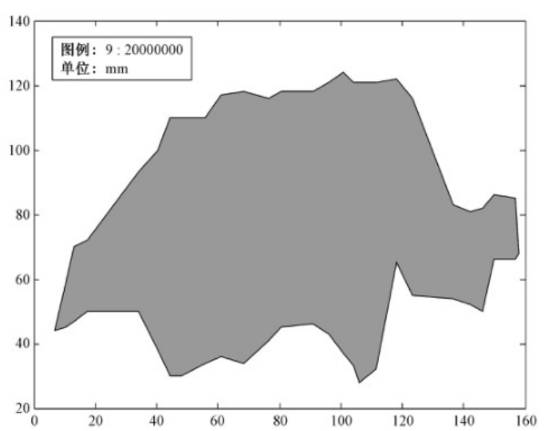

图 欧洲某个国家的地图

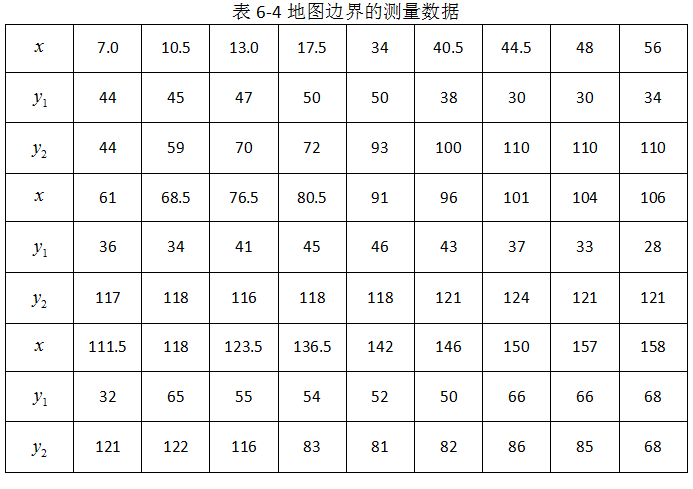

       根据地图的比例我们知道**地图上18mm相当于实际中的40km**，试由测量数据计算该国土的近似面积，并与它的精确值41288${\textrm{km}}^2$进行比较。

2) 模型的假设

我们进行如下假设：

$\cdot$假设测量的地图和数据均是准确的。

$\cdot$假设由最西边界点与最东边界点分为上下两条连续的边界曲线，边界内的所有土地均为该国国土。

$\cdot$假设从最西边界点到最东边界点的变量$x\in \left\lbrack a,b\right\rbrack$,划分$\left\lbrack a,b\right\rbrack$为n个小段$\left\lbrack x_{i-1} ,x_i \right\rbrack$，并由此将国土分为n小块。设每一小块均为X型区域，即作垂直于x轴的直线穿过该区域，直线与边界曲线最多只有两个交点。

3) 模型的建立与求解

首先利用MATLAB对**上下边界分别进行三次样条和分段三次Hermite插值**，得到加密曲线。此时，设上边界函数为$f_2 \left(x\right)$，下边界函数为$f_1 \left(x\right)$，则由定积分定义可知曲线所围区域面积为：


$$S=\int_a^b f\left(x\right)\textrm{dx}=\lim_{n\to \infty } \sum_{i=1}^n \left\lbrack f_2 \left(\xi_i \right)-f_1 \left(\xi_i \right)\right\rbrack \Delta x_i$$


其中$\xi_i \in \left\lbrack x_{i-1} ,x_i \right\rbrack$。

程序如下：

x=[7.0 10.5 13.0 17.5 34 40.5 44.5 48 56 61 68.5 76.5 80.5...
    91 96 101 104 106 111.5 118 123.5 136.5 142 146 150 157 158];  % x轴坐标
y1=[44 45 47 50 50 38 30 30 34 36 34 41 45 46 43 37 33 28 ...
    32 65 55 54 52 50 66 66 68];  % y轴上半部分的坐标
y2=[44 59 70 72 93 100 110 110 110 117 118 116 118 118 121 ...
    124 121 121 121 122 116 83 81 82 86 85 68];  % y轴下半部分坐标
xi=7:0.1:158;  % 加密x轴坐标
method={'pchip','spline'};  % 插值方法
for k=1:2
    figure(k)  % 产生图形窗口
    yi1(k,:)=interp1(x,y1,xi,char(method(k)));  % 一维插值
    yi2(k,:)=interp1(x,y2,xi,char(method(k)));  % 一维插值
    S=(trapz(xi,yi2(k,:))-trapz(xi,yi1(k,:)))/18^2*40^2;  % 数值积分求解
    r=abs(S-41288)/S  % 求误差
    fill([xi,fliplr(xi)],[yi1(k,:),fliplr(yi2(k,:))],[0.8,0.7,0.3])  % 图形填充
    text(90,135,['国土面积：S=',num2str(S),'km^2'])  % 添加标注
    text(90,127,['误差：R=',num2str(100*r),'%'])  % 添加标注
    annotation('textbox','Position',[0.16 0.8 0.22 0.09],...
        'String',{'图例：9:20000000','单位：mm'});  % 添加文本框
    title(['国土轮廓的',char(method(k)),'插值结果'])  % 添加标题
end
figure
plot(xi,[diff(yi1);diff(yi2)])  % 绘制误差曲线
title('pchip插值与spline插值的误差曲线')  % 添加标题

       由上述两个插值地图比较可知，利用pchip插值得到的结果更趋于精确值。

img = imread('timg.jpg');
figure
imshow(img)
img_part = img(1:100,1:100,:);
figure
imshow(img_part)
img_shrink = img(1:4:end,1:4:end,:);
figure
imshow(img_shrink)
imgSize = size(img_shrink);
[x y] = meshgrid(1:4:((imgSize(2)-1)*4+1),1:4:((imgSize(1)-1)*4+1));
[xx yy] = meshgrid(1:((imgSize(2)-1)*4+1),1:((imgSize(1)-1)*4+1));
for i =1:3
    img_expand(:,:,i) = interp2(x,y,double(img_shrink(:,:,i)),xx,yy,"spline");
end
img_expand = uint8(round(img_expand,0));
figure
imshow(img_expand)

**作业：**

1、天文学家在1914年8月份的7次观测中，测得地球与金星之间的距离（单位：m），并取其常用对数值与日期的一组历史数据，如表所示，试推断何时金星与地球的距离的对数值为9.935799

2、在一次对沙堆形状测量的时候得到部分高度信息，如表所示，利用二维插值计算该区域内其他点的高度。